# Quantum Phase Estimation 

(References: Section 5.2 of Quantum Computation and Quantum Information. M. Nielsen, and I. L. Chuang, this example is inspired by [https://pennylane.ai/qml/demos/tutorial_qpe](https://pennylane.ai/qml/demos/tutorial_qpe) )

Let $U$ be a unitary operator an $|u\rangle$ its eigenvector with eigenvalue $e^{2\pi i\phi}$. Quantum phase estimation is an algorithm to estimate $\phi$.

In this example we want to estimate the phase of the unitary

$$U = \left[ \begin{array}{cc} 1 & 0 \\ 0 &e^{2\pi i 0.8} \end{array}\right]$$. 

This unitary has phase 0.8, which is 0.1100110011... in binary, with corresponding eigenvector $|1\rangle$. The quantum phase estimation uses two registers. The first one is the estimation register. The qubits here start in state $|0\rangle$ and the number of qubits corresponds to the number of binary digits (bits) of the phase that can be estimated. The second register is prepared in state $|u\rangle$.

Assume we want to estimate the phase of our example with four digits. Then our total circuit needs 5 qubits, four estimation qubit and one that stores the eigenvector $|1\rangle$.

Circuit = qclab.QCircuit(5);

The first step of the algorithm is to apply Hadamard gates to all estimation qubits to bring them in a uniform superposition:

H = @qclab.qgates.Hadamard;
Circuit.push_back(H(0))
Circuit.push_back(H(1))
Circuit.push_back(H(2))
Circuit.push_back(H(3))

As next step one performs controlled $U$, $U^2$, $U^4$ and $U^8$  operations on $|u\rangle$.  For that we use the multi controlled matrix gate.

phase = 0.8;
unitary = [1,0; 0,exp(2*pi*1i*phase)];

CU = @qclab.qgates.MCMatrixGate;

%U1
U = CU(3,4,unitary);
Circuit.push_back(U)

%U2
U2 = CU(2,4,unitary^2);

Circuit.push_back(U2)

%U4
U4 = CU(1,4,unitary^4);
Circuit.push_back(U4)

%U8
U8 = CU(0,4,unitary^8);
Circuit.push_back(U8)

Now we apply a inverse Fourier transformation to the estimation qubits (see example QuantumFourierTransform.m).  

qftcircuit = qclab.QCircuit( 4 ) ;
qftCircuit( qftcircuit );
%invert qft
inverseqftcircuit = qftcircuit.ctranspose();
%draw as block
inverseqftcircuit.asBlock('inverse qft')
%add to circuit
Circuit.push_back(inverseqftcircuit)

Finally we measure the estimation qubits to get our estimate.

M = @qclab.Measurement;
Circuit.push_back(M(0))
Circuit.push_back(M(1))
Circuit.push_back(M(2))
Circuit.push_back(M(3))


Let us draw the whole circuit:

Circuit.draw()

     ┏━┓                         ┏━━━━━━━━━━━━━┓ ┏━┓ 
q0: ━┫H┣━━━━━━━━━━━━━━━━━━━━━●━━━┫             ┣━┫M┣━
     ┗━┛                     ┃   ┃             ┃ ┗━┛ 
     ┏━┓                     ┃   ┃             ┃ ┏━┓ 
q1: ━┫H┣━━━━━━━━━━━━━━━●━━━━━╋━━━┫             ┣━┫M┣━
     ┗━┛               ┃     ┃   ┃ inverse qft ┃ ┗━┛ 
     ┏━┓               ┃     ┃   ┃             ┃ ┏━┓ 
q2: ━┫H┣━━━━━━━━━●━━━━━╋━━━━━╋━━━┫             ┣━┫M┣━
     ┗━┛         ┃     ┃     ┃   ┃             ┃ ┗━┛ 
     ┏━┓         ┃     ┃     ┃   ┃             ┃ ┏━┓ 
q3: ━┫H┣━━━●━━━━━╋━━━━━╋━━━━━╋━━━┫             ┣━┫M┣━
     ┗━┛   ┃     ┃     ┃     ┃   ┗━━━━━━━━━━━━━┛ ┗━┛ 
         ┏━┻━┓ ┏━┻━┓ ┏━┻━┓ ┏━┻━┓                     
q4: ━━━━━┫ U ┣━┫ U ┣━┫ U ┣━┫ U ┣━━━━━━━━━━━━━━━━━━━━━
         ┗━━━┛ ┗━━━┛ ┗━━━┛ ┗━━━┛                     


fID = fopen('phase_circuit.tex','w');
Circuit.toTex(fID, 'S');
fclose(fID);

To get our estimate we need to simulate the circuit.

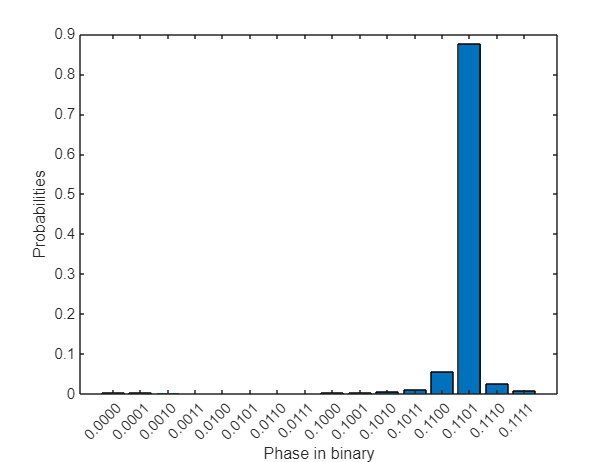

sim = Circuit.simulate('00001');
bar(sim.probabilities);
xticks(1:length(sim.results)); 
xticklabels("0." + sim.results); 
xlabel('Phase in binary');
ylabel('Probabilities');

We estimated 0.8 as 0.1101 in binary which is 0.8125 in decimal.

It is also possible to simulate multiple shots; a seed can be set via the `simulate` function.

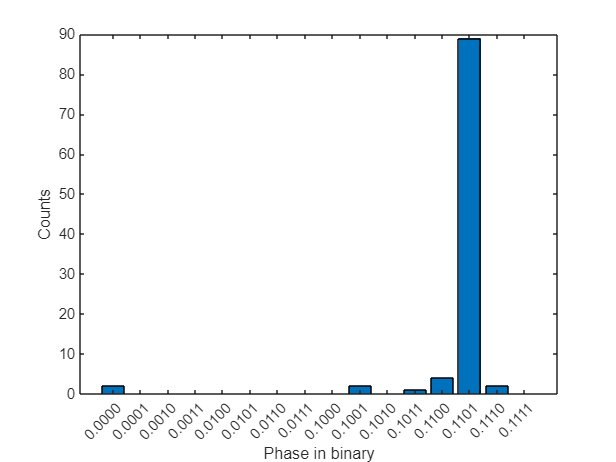

bar(sim.counts(100));
xticks(1:length(sim.results)); 
xticklabels("0." + sim.results); 
xlabel('Phase in binary');
ylabel('Counts');


%quantum fourier transform
function qftCircuit( circuit )
  H = @qclab.qgates.Hadamard ;
  CP = @qclab.qgates.CPhase ;
  SWAP = @qclab.qgates.SWAP ;
  
  n = double(circuit.nbQubits) ;
  % B blocks
  for i = 0 : n - 1
    % Hadamard
    circuit.push_back( H( i ) );
    % diagonal blocks
    for j = 2 : n-i
      control = j + i - 1 ;
      theta = 2*pi/2^j ;
      circuit.push_back( CP( control, i, theta ) ) ;
    end
  end
  
  %swaps
  for i = 0 : floor(n/2) - 1
    circuit.push_back( SWAP( i, n - i - 1 ) );
  end
end
